 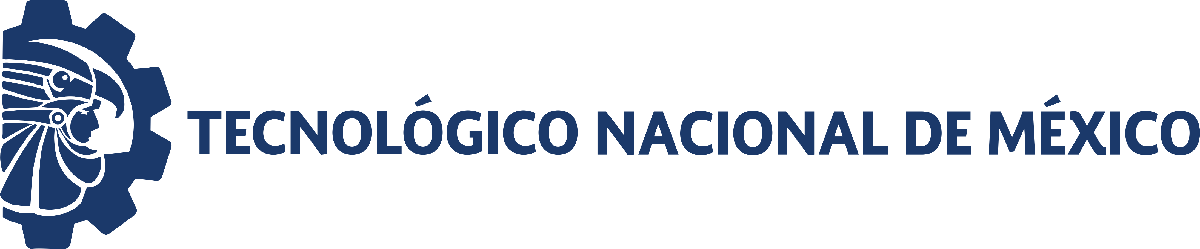                                 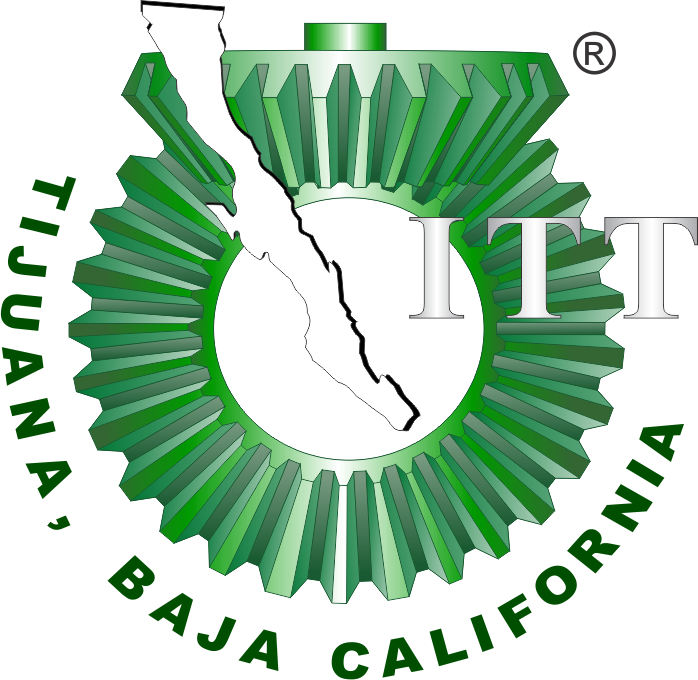

# Proyecto Final

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

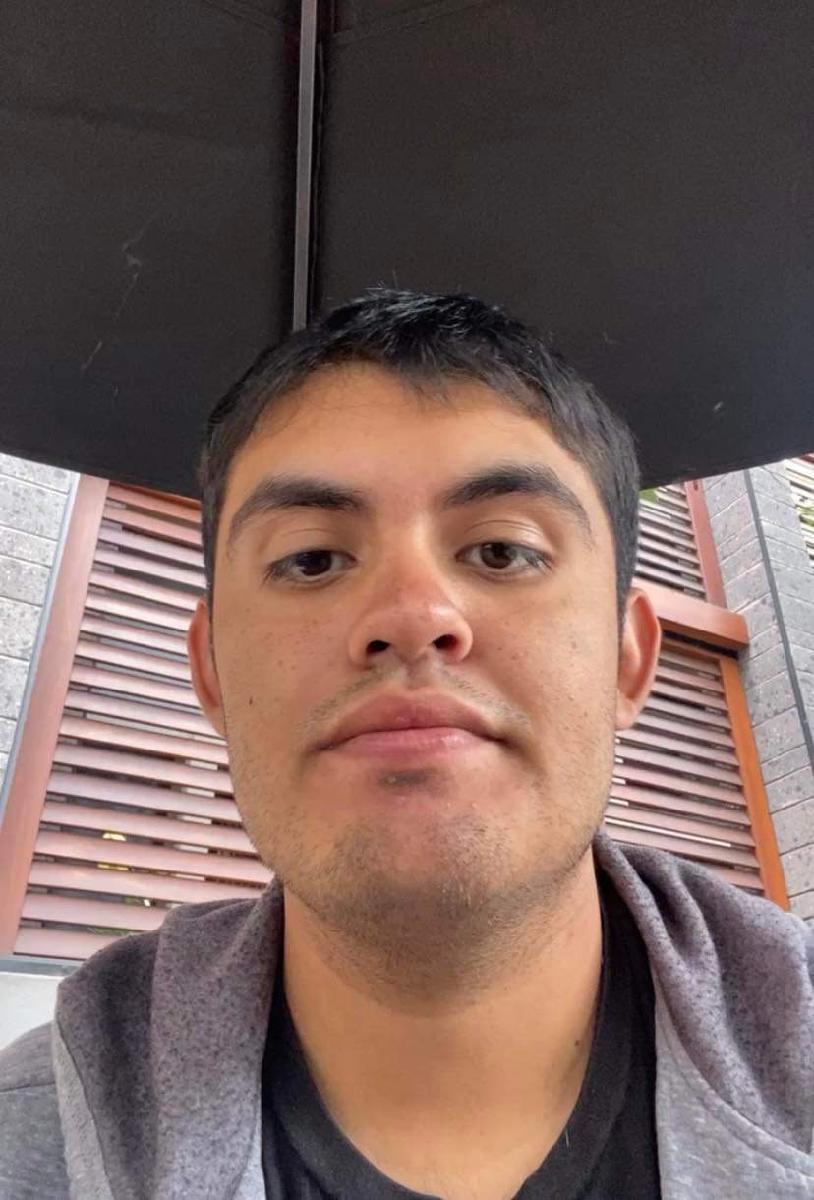

Nombre del alumno: **Andres Martin Bañuelos Elias**

Número de control: **21212142**

Correo institucional: **l21212142@tectijuana.edu.mx**

Carrera:** Ingenieria Biomedica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

**Objetive: **To integrate specific competencies related to the modeling, analysis, and control of biological systems, in order to illustrate and predict their dynamics in both the short and long term. The goal is to lay the groundwork for the development of digital twins capable of addressing and solving problems within the field of Systems Biology.

## Simulation Data

    tiempo    x(t)      y(t)     Z(t) 
    ______    _____    ______    _____

       0      0.517    19.939    0.281
       7       0.58    19.578    0.609
      14      0.726    18.678    1.063
      21      0.965    16.215    1.758
      28      1.282    14.005    2.752
      35      1.825    11.467    3.975
      42      2.473     8.096    4.895
      49      2.974     4.327    6.096
      56       3.43     1.287    7.152
      63      3.717     0.194    7.328
      70      3.829     0.056    7.232



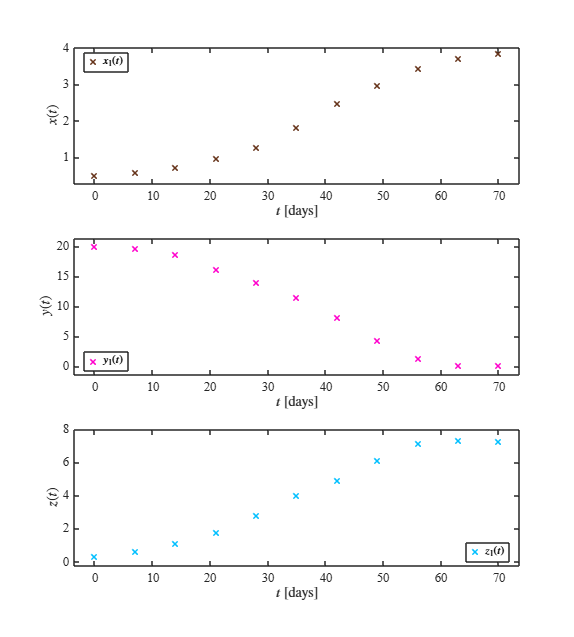

clc; clear; close all; warning('off','all')
filename = 'data2.csv';
sys = readmatrix(filename);
to = sys(:,1);
x1 = sys(:,2);
y1 = sys(:,3);
Z1 = sys(: ,4);
T = array2table([to, x1,y1,Z1], 'VariableNames', {'tiempo', 'x(t)', 'y(t)', 'Z(t)'});
disp(T); plotdata(to, x1, y1, Z1); saveas(gcf, 'RawData.pdf');

## Smooth Data

clc; clear; close all; warning('off','all');
filename = 'data2.csv';
sys = readmatrix(filename);
to = sys(:,1);
x1 = sys(:,2);
y1 = sys(:,3);
Z1 = sys(:,4);

windowSize = 5;
x1_smooth = movmean(x1, windowSize);
y1_smooth = movmean(y1, windowSize);
Z1_smooth = movmean(Z1, windowSize);

T_smooth = array2table([to, x1_smooth, y1_smooth, Z1_smooth], ...
    'VariableNames', {'tiempo', 'x(t)', 'y(t)', 'z(t)'});
disp(T_smooth);%writetable(T_smooth, 'data2_suavizado.csv'); 

    tiempo     x(t)       y(t)       z(t)  
    ______    _______    _______    _______

       0      0.60767     19.398      0.651
       7        0.697     18.602    0.92775
      14        0.814     17.683     1.2926
      21       1.0756     15.989     2.0314
      28       1.4542     13.692     2.8886
      35       1.9038     10.822     3.8952
      42       2.3968     7.8364      4.974
      49       2.8838     5.0742     5.8892
      56       3.2846      2.792     6.5406
      63       3.4875      1.466      6.952
      70       3.6587    0.51233     7.2373



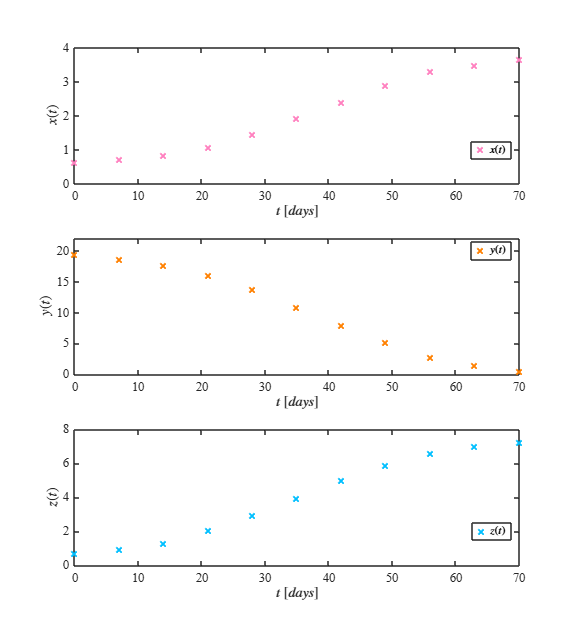

plotEDOs_fit(to, x1_smooth, y1_smooth, Z1_smooth);saveas(gcf, 'SmoothData.pdf');

## Nonlinear Regression

The resulting equations from the nonlinear regression, obtained using the Eureqa software, are as follows:


$$\frac{\textrm{dx}}{\textrm{dt}}=P_1 \textrm{xy}+P_2 \textrm{xyz}$$



$$\frac{\textrm{dy}}{\textrm{dt}}=P_3 y-P_4 \textrm{xy}$$



$$\frac{\textrm{dz}}{\textrm{dt}}=P_5 z-P_6 \textrm{yz}$$



Sample size (n): 11
Parameters estimated: 6
Degrees of freedom: 27
R-squared: 0.9998
Corrected AIC: -53.5645

    Param     Estimate         SE           MoE                  CI95                pValue  
    _____    __________    __________    __________    ________________________    __________

    "p1"     0.00046445    0.00011144    0.00022866    0.00023579    0.00069311    0.00028361
    "p2"     0.00078488    4.7378e-05    9.7212e-05    0.00068767     0.0008821    1.1357e-15
    "p3"       0.015099    0.00051026      0.001047      0.014052      0.016146    4.1008e-22
    "p4"        0.03085    0.00068236     0.0014001       0.02945       0.03225    5.4925e-27
    "p5"      0.0042856     0.0007983      0.001638     0.0026476     0.0059236    1.1335e-05
    "p6"      0.0029086   

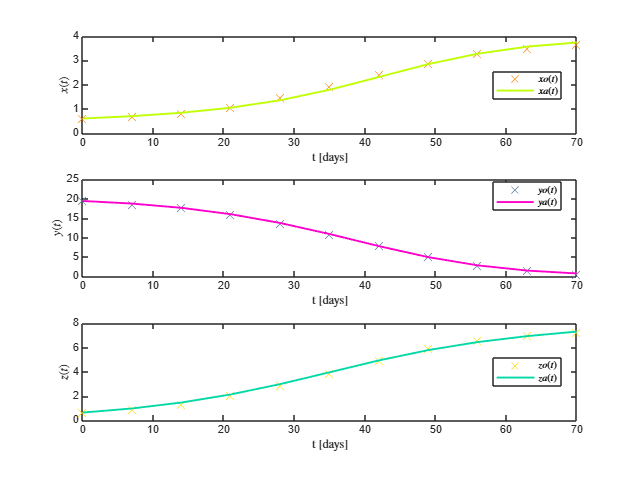

warning('off')
sys = readmatrix('data2_suavizado.csv');
to = sys(:,1);
xo = sys(:,2);
yo = sys(:,3);
zo = sys(:,4);
P0 = [
    0.00115591860282494;   
    0.000608183514299159;  
    0.0139308044869223;    
    0.0287876736667008;    
    0.00251665147568222;   
    0.00321466323165287    
];
[mdl, xa, ya, za] = Varied(to, xo, yo, zo, P0); saveas(gcf, 'Nonlinear Regresion.pdf');

## Model fitting

*The contents include general information, data preprocessing (smoothing and normalization), nonlinear regression methods, model fitting, and system analysis using the Jacobian matrix and equilibrium points. Additional sections cover local stability, prediction algorithms (such as 2t prediction), and corresponding plots for both raw and processed data.*

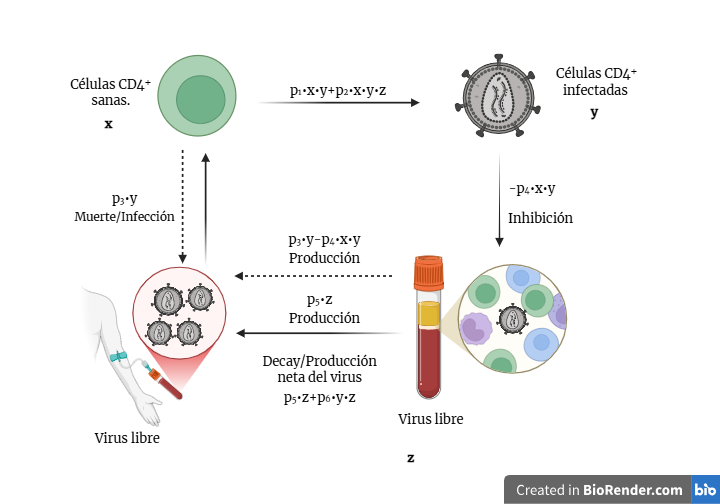


$$\begin{array}{l}
x=\textrm{Healthy}\;\textrm{CD4}+\textrm{cells}\\
y=\textrm{Infected}\;\textrm{CD4}+\textrm{cells}\\
z=\textrm{Free}\;\textrm{virus}
\end{array}$$


Equation 1: Healthy cells (x):${\;P}_1 \textrm{xy}+P_2 \textrm{xyz}$ 

**Interpretation:**

- This models the dynamics of healthy CD4+ cells.

- The diagram shows that healthy cells are **lost due to infection** when they interact with infected cells y and free virus z.

Equation 2: Infected cells (y): $P_3 y-P_4 \textrm{xy}$

**Interpretation:**

- $P_3 y$: Persistence or reproduction of infected cells.

- $-P_4 \textrm{xy}$: Suppression or elimination of infected cells by healthy cells.

- The diagram shows the transition from healthy to infected and the inhibition effect.

 Equation 3: Free virus (z): $P_5 z-P_6 \mathrm{yz}$

**Interpretation:**

- $P_5 z$: Direct replication of free virus.

- $-P_6 \mathrm{yz}$: Additional virus production driven by infected cells.

- The diagram shows a feedback loop: the virus is produced by infected cells and also amplifies itself.

## Jacobian Matrix and Equilibrium Points

clc; clear; close all; warning('off','all')

syms x y z
p = sym('p', [1 7]);  

  dx = p(1) * x .* y + p(2) * x .* y .* z;
    dy = p(3) * y - p(4) * x .* y;
    dz = p(5) * z + p(6) * y .* z;

J = jacobian([dx, dy, dz], [x, y, z]);
fprintf('Jacobian matrix of the system:\n');disp(J)

Jacobian matrix of the system:


$$\left(\begin{array}{ccc} p_{1}\,y+p_{2}\,y\,z & p_{1}\,x+p_{2}\,x\,z & p_{2}\,x\,y\\ -p_{4}\,y & p_{3}-p_{4}\,x & 0\\ 0 & p_{6}\,z & p_{5}+p_{6}\,y \end{array}\right)$$

eq1 = dx == 0;
eq2 = dy == 0;
eq3 = dz == 0;
edos = solve([eq1, eq2, eq3], [x, y, z], 'Real', true);

n = length(edos.x);
fprintf('Equilibrium Points of the system:\n');fprintf('The system has %d equilibrium point(s).\n\n', n);

Equilibrium Points of the system:
The system has 2 equilibrium point(s).



for i = 1:min(3,n)
    X = edos.x(i);
    Y = edos.y(i);
    Z = edos.z(i);
    fprintf('Equilibrium point %d:\n', i);
    disp([X, Y, Z])
end

Equilibrium point 1:


$$\left(\begin{array}{ccc} 0 & 0 & 0 \end{array}\right)$$

Equilibrium point 2:


$$\left(\begin{array}{ccc} \frac{p_{3}}{p_{4}} & -\frac{p_{5}}{p_{6}} & -\frac{p_{1}}{p_{2}} \end{array}\right)$$

## Local estability

clc; clear; close all; warning('off','all')
p = [
    0.00115591860282494;   
    0.000608183514299159; 
    0.0139308044869223;    
    0.0287876736667008;    
    0.00251665147568222;  
    0.00321466323165287    
];
syms x y z
dx = p(1)*x*y + p(2)*x*y*z;
dy = p(3)*y - p(4)*x*y;
dz = p(5)*z + p(6)*y*z;
edos = solve([dx == 0, dy == 0, dz == 0], [x, y, z]);
J = [ diff(dx,x), diff(dx,y), diff(dx,z);
      diff(dy,x), diff(dy,y), diff(dy,z);
      diff(dz,x), diff(dz,y), diff(dz,z)];
n_eq = length(edos.x);
for k = 1:n_eq
    x0 = double(edos.x(k));
    y0 = double(edos.y(k));
    z0 = double(edos.z(k));    
    J_eval = double(subs(J, {x,y,z}, {x0,y0,z0}));
    L = eig(J_eval);
    L = sort(L,'descend');
    L1 = L(1); L2 = L(2); L3 = L(3);
    var = {sprintf('Equilibrium_%d', k)};
    Lambdas = table(L1, L2, L3, 'RowNames', var); 
    disp(Lambdas)
end

                        L1                 L2                       L3          
                     _________    _____________________    _____________________

    Equilibrium_1    0.0031657    -0.0015829+0.0027416i    -0.0015829-0.0027416i

                        L1          L2        L3
                     ________    _________    __

    Equilibrium_2    0.013931    0.0025167    0 



## Data Normalized

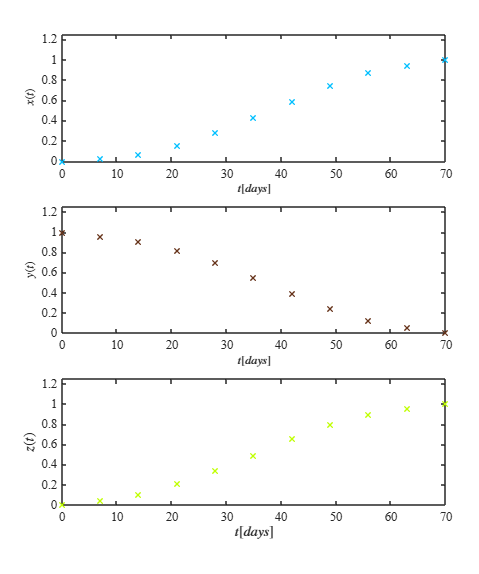

sys = readmatrix('data2_suavizado.csv');
to = sys(:,1);
x1 = sys(:,2);
y1 = sys(:,3);
Z1 = sys(:,4);
x1 = smoothdata(x1);
y1 = smoothdata(y1);
Z1 = smoothdata(Z1);
T = table(to, xo, yo, zo, 'VariableNames', {'Tiempo', 'X_suave', 'Y_suave', 'Z_suave'}); graficarSuavizado(T); saveas(gcf, 'Data Normalized.pdf');

## 2t prediction

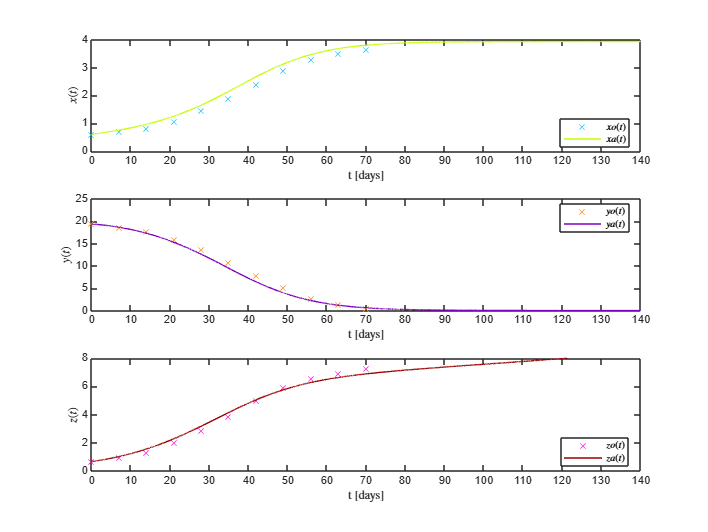

warning('off')
filename = 'data2_suavizado.csv';
sys = readmatrix(filename);
t = sys(:,1);
x = sys(:,2);
y = sys(:,3);
z = sys(:,4);
P0 = [
    0.00115591860282494;   
    0.000608183514299159; 
    0.0139308044869223;    
    0.0287876736667008;    
    0.00251665147568222;  
    0.00321466323165287    
];
dt = 1E-2;
tend = 140;
[tp, xp, yp, zp] = Predict(x(1), y(1), z(1), dt, tend, P0);
plotXYZPredict(t, x, y, z, tp, xp, yp, zp);saveas(gcf, '2T.pdf');

## Conclusion 

This project has enabled the integration of advanced mathematical tools with real experimental data to construct a dynamic model that accurately describes the behavior of a nonlinear system. Throughout the different stages from data collection to simulation and model validation  a deep understanding was developed of both the biological processes involved and the mathematical analysis techniques required for their study.

The use of nonlinear regression facilitated the identification of appropriate parameters, while statistical significance and goodness-of-fit tests ensured the reliability of the results. Additionally, the local and global stability analysis allowed us to explore the qualitative dynamics of the model, providing key insights into its long-term behavior. The simulations carried out during the in silico experimentation stage demonstrated that the model not only fits the available data but also has good predictive potential.

Ultimately, this practice highlights the importance of an interdisciplinary approach in the mathematical modeling of real-world phenomena, where the validity of the model depends not only on its numerical fit but also on its biological consistency and ability to offer useful and meaningful predictions.

## Function

## Raw data plot

function plotdata(t, x, y, z)
    Mecambiareaindustrial = [
        0.60, 0.00, 0.00;  
        0.75, 1.00, 0.00;  
        0.00, 0.75, 1.00;  
        0.50, 0.00, 0.75;  
        1.00, 0.50, 0.00;  
        0.40, 0.20, 0.10;  
        1.00, 0.00, 0.80;  
        1.00, 0.50, 0.75;  
        0.00, 0.85, 0.65;  
        0.30, 0.45, 0.60   
    ];

    rng('shuffle');
    indices = randperm(size(Mecambiareaindustrial,1), 3);
    c1 = Mecambiareaindustrial(indices(1), :);
    c2 = Mecambiareaindustrial(indices(2), :);
    c3 = Mecambiareaindustrial(indices(3), :);

    t_min = min(t);
    t_max = max(t);
    t_margin = (t_max - t_min) * 0.05;
    x_axis = [t_min - t_margin, t_max + t_margin];

    %% Crear una sola figura con subplots
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 2, 18, 20])

    % Gráfica x(t)
    subplot(3,1,1)
    plot(t, x, 'x', 'LineWidth', 1.2, 'Color', c1, 'DisplayName', '$x_1(t)$')
    xlabel('$t$ [days]', 'Interpreter', 'latex', 'FontName', 'Times New Roman')
    ylabel('$x(t)$', 'Interpreter', 'latex', 'FontName', 'Times New Roman')
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    xlim(x_axis)
    ylim padded
    grid off
    legend('Interpreter', 'latex', 'Location', 'best')

    % Gráfica y(t)
    subplot(3,1,2)
    plot(t, y, 'x', 'LineWidth', 1.2, 'Color', c2, 'DisplayName', '$y_1(t)$')
    xlabel('$t$ [days]', 'Interpreter', 'latex', 'FontName', 'Times New Roman')
    ylabel('$y(t)$', 'Interpreter', 'latex', 'FontName', 'Times New Roman')
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    xlim(x_axis)
    ylim padded
    grid off
    legend('Interpreter', 'latex', 'Location', 'best')

    % Gráfica z(t)
    subplot(3,1,3)
    plot(t, z, 'x', 'LineWidth', 1.2, 'Color', c3, 'DisplayName', '$z_1(t)$')
    xlabel('$t$ [days]', 'Interpreter', 'latex', 'FontName', 'Times New Roman')
    ylabel('$z(t)$', 'Interpreter', 'latex', 'FontName', 'Times New Roman')
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    xlim(x_axis)
    ylim padded
    grid off
    legend('Interpreter', 'latex', 'Location', 'best')

    set(gcf, 'PaperUnits', 'centimeters', 'PaperPosition', [0 0 18 20]);
    print(gcf, 'datos_txyz.pdf', '-dpdf', '-r300');
end


## Smooth data plot

function plotEDOs_fit(t, x, y, z)
    Mecambiareaindustrial = [
        0.60, 0.00, 0.00;  
        0.75, 1.00, 0.00;  
        0.00, 0.75, 1.00;  
        0.50, 0.00, 0.75;  
        1.00, 0.50, 0.00;  
        0.40, 0.20, 0.10;  
        1.00, 0.00, 0.80;  
        1.00, 0.50, 0.75;  
        0.00, 0.85, 0.65;  
        0.30, 0.45, 0.60   
    ];  

    rng('shuffle');  
    indices = randperm(size(Mecambiareaindustrial,1), 3); 
    c1 = Mecambiareaindustrial(indices(1), :);
    c2 = Mecambiareaindustrial(indices(2), :);
    c3 = Mecambiareaindustrial(indices(3), :);

    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 10, 18, 20])

    % x(t)
    subplot(3,1,1)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on;
    plot(t, x, 'x', 'LineWidth', 1.5, 'Color', c1, 'DisplayName', '$x(t)$')
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$x(t)$', 'Interpreter', 'latex')
    xticks(0:10:70); yticks(0:1:4)
    xlim([0 70]); ylim([0 4])
    legend('Interpreter', 'latex', 'Location', 'best')

    % y(t)
    subplot(3,1,2)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on;
    plot(t, y, 'x', 'LineWidth', 1.5, 'Color', c2, 'DisplayName', '$y(t)$')
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$y(t)$', 'Interpreter', 'latex')
    xlim([min(t), max(t)])
    ylim([0 22])
    legend('Interpreter', 'latex', 'Location', 'best')

    % z(t)
    subplot(3,1,3)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on;
    plot(t, z, 'x', 'LineWidth', 1.5, 'Color', c3, 'DisplayName', '$z(t)$')
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$z(t)$', 'Interpreter', 'latex')
    xticks(0:10:70); yticks(0:2:8)
    xlim([0 70]); ylim([0 8])
    legend('Interpreter', 'latex', 'Location', 'best')

    % Guardar en PDF si se desea
    % print(gcf, 'EDO_plot.pdf', '-dpdf', '-bestfit')
end



## Nonlinear regression algorithm

function [mdl, xa, ya, za] = Varied(to, xo, yo, zo, p0)
    x0 = xo(1); y0 = yo(1); z0 = zo(1);
    to3 = [to; to; to];
    fo = [xo; yo; zo];

    function fi = model(p, tvec)
        dt = 0.01;
        tmat = reshape(tvec, [], 3);
        t = tmat(:,1);
        time = (0:dt:max(t))';
        n = numel(time);

        x = zeros(n,1); x(1) = x0;
        y = zeros(n,1); y(1) = y0;
        z = zeros(n,1); z(1) = z0;

        for i = 1:n-1
            [dx, dy, dz] = f(x(i), y(i), z(i), p);
            xp = x(i) + dx*dt;
            yp = y(i) + dy*dt;
            zp = z(i) + dz*dt;

            xp = max(xp, 1e-10);
            yp = max(yp, 1e-10);
            zp = max(zp, 1e-10);

            [dxp, dyp, dzp] = f(xp, yp, zp, p);

            x(i+1) = x(i) + (dx + dxp)*dt/2;
            y(i+1) = y(i) + (dy + dyp)*dt/2;
            z(i+1) = z(i) + (dz + dzp)*dt/2;

            if any(~isfinite([x(i+1), y(i+1), z(i+1)]))
                error('Valor no finito en t=%.4f', time(i+1));
            end
        end

        xi = interp1(time, x, t, 'linear', NaN);
        yi = interp1(time, y, t, 'linear', NaN);
        zi = interp1(time, z, t, 'linear', NaN);

        if any(isnan([xi; yi; zi]))
            error('Interpolación devolvió NaN');
        end

        fi = [xi; yi; zi];
    end

   function [dx, dy, dz] = f(x, y, z, p)
    dx = p(1) * x .* y + p(2) * x .* y .* z;
    dy = p(3) * y - p(4) * x .* y;
    dz = p(5) * z + p(6) * y .* z;
   end
    mdl = fitnlm(to3, fo, @model, p0);

    fa = mdl.Fitted;
    fn = reshape(fa, [], 3);
    xa = fn(:,1);
    ya = fn(:,2);
    za = fn(:,3);

    coef = mdl.Coefficients;
    Estimate = coef.Estimate;
    SE = coef.SE;
    pValue = coef.pValue;
    CI95 = coefCI(mdl, 0.05);
    dof = mdl.DFE;
    tval = tinv(0.975, dof);
    MoE = SE * tval;

    Params = ["p1"; "p2"; "p3"; "p4"; "p5"; "p6"];
    Results = table(Params, Estimate, SE, MoE, CI95, pValue, ...
        'VariableNames', {'Param','Estimate','SE','MoE','CI95','pValue'});

    fprintf('\nSample size (n): %d', numel(xo));
    fprintf('\nParameters estimated: %d', numel(p0));
    fprintf('\nDegrees of freedom: %d', dof);
    fprintf('\nR-squared: %.4f', mdl.Rsquared.Ordinary);
    fprintf('\nCorrected AIC: %.4f\n\n', mdl.ModelCriterion.AICc);
    disp(Results);

    X_plot = [xo, xa];
    Y_plot = [yo, ya];
    Z_plot = [zo, za];
    plotXYZResults(to, X_plot, Y_plot, Z_plot);
end

## Nonlinear regression plot

function plotXYZResults(t, X, Y, Z)
    Mecambiareaindustrial = [
        0.60, 0.00, 0.00;  
        0.75, 1.00, 0.00;  
        0.00, 0.75, 1.00;  
        0.50, 0.00, 0.75;
        1.00, 0.50, 0.00;  
        0.40, 0.20, 0.10;  
        1.00, 0.00, 0.80;  
        1.00, 0.85, 0.00; 
        0.00, 0.85, 0.65;  
        0.30, 0.45, 0.60   
    ];    
    rng('shuffle'); 
    indices = randperm(size(Mecambiareaindustrial,1), 6); 
    c1_obs = Mecambiareaindustrial(indices(1), :);
    c1_mod = Mecambiareaindustrial(indices(2), :);
    c2_obs = Mecambiareaindustrial(indices(3), :);
    c2_mod = Mecambiareaindustrial(indices(4), :);
    c3_obs = Mecambiareaindustrial(indices(5), :);
    c3_mod = Mecambiareaindustrial(indices(6), :);

    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,15])
    set(gca,'FontName','Times New Roman')
    fontsize(12,'points')

    %% Subplot X
    subplot(3,1,1)
    hold on; box on;
    plot(t, X(:,1), 'x', 'Color', c1_obs, 'MarkerSize', 9)
    plot(t, X(:,2), '-', 'Color', c1_mod, 'LineWidth', 1.5)
    xlabel('t [days]','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    legend({'$xo{(t)}$','$xa{(t)}$'}, 'Interpreter','latex', 'Location', 'Best')
    xticks(0:10:70); yticks(0:1:4)
    xlim([0 70]); ylim([0 4])

    %% Subplot Y
    subplot(3,1,2)
    hold on; box on;
    plot(t, Y(:,1), 'x', 'Color', c2_obs, 'MarkerSize', 9)
    plot(t, Y(:,2), '-', 'Color', c2_mod, 'LineWidth', 1.5)
    xlabel('t [days]','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    legend({'$yo{(t)}$','$ya{(t)}$'}, 'Interpreter','latex', 'Location', 'Best')
    xticks(0:10:70); yticks(0:5:25)
    xlim([0 70]); ylim([0 25])

    %% Subplot Z
    subplot(3,1,3)
    hold on; box on;
    plot(t, Z(:,1), 'x', 'Color', c3_obs, 'MarkerSize', 9)
    plot(t, Z(:,2), '-', 'Color', c3_mod, 'LineWidth', 1.5)
    xlabel('t [days]','Interpreter','latex')
    ylabel('$z(t)$','Interpreter','latex')
    legend({'$zo{(t)}$','$za{(t)}$'}, 'Interpreter','latex', 'Location', 'Best')
    xticks(0:10:70); yticks(0:2:8)
    xlim([0 70]); ylim([0 8])
end

## Data Normalized Plot

function graficarSuavizado(T)
    figure('Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,15,18])

    Mecambiareaindustrial = [
        0.60, 0.00, 0.00;  
        0.75, 1.00, 0.00;  
        0.00, 0.75, 1.00;  
        0.50, 0.00, 0.75;
        1.00, 0.50, 0.00;  
        0.40, 0.20, 0.10;  
        1.00, 0.00, 0.80;  
        1.00, 0.85, 0.00; 
        0.00, 0.85, 0.65;  
        0.30, 0.45, 0.60   
    ];    

    rng('shuffle'); 
    indices = randperm(size(Mecambiareaindustrial,1), 4); 
    c1 = Mecambiareaindustrial(indices(1), :);
    c2 = Mecambiareaindustrial(indices(2), :);
    c3 = Mecambiareaindustrial(indices(3), :);
    c4 = Mecambiareaindustrial(indices(4), :);

    t = T.Tiempo;
    x = (T.X_suave - min(T.X_suave)) / (max(T.X_suave) - min(T.X_suave));
    y = (T.Y_suave - min(T.Y_suave)) / (max(T.Y_suave) - min(T.Y_suave));
    z = (T.Z_suave - min(T.Z_suave)) / (max(T.Z_suave) - min(T.Z_suave));
    pos1 = [0.13 0.72 0.8 0.22]; pos2 = [0.13 0.42 0.8 0.22]; pos3 = [0.13 0.12 0.8 0.22];

    axes('Position', pos1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on;
    plot(t, x, 'x', 'LineWidth', 1, 'Color', c1)
    xlabel('$t [days]$', 'Interpreter', 'latex')
    ylabel('$x(t)$', 'Interpreter', 'latex')
    xlim([min(t), max(t)]); ylim([0 1.25]); yticks(0:0.2:1.25)

    axes('Position', pos2)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on;
    plot(t, y, 'x', 'LineWidth', 1, 'Color', c2)
    xlabel('$t [days]$', 'Interpreter', 'latex')
    ylabel('$y(t)$', 'Interpreter', 'latex')
    xlim([min(t), max(t)]); ylim([0 1.25]); yticks(0:0.2:1.25)

    axes('Position', pos3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on;
    plot(t, z, 'x', 'LineWidth', 1, 'Color', c3)
    xlabel('$t [days]$', 'Interpreter', 'latex')
    ylabel('$z(t)$', 'Interpreter', 'latex')
    xlim([min(t), max(t)]); ylim([0 1.25]); yticks(0:0.2:1.25)
end

## 2t prediction algorithm

function [t, x, y, z] = Predict(x0, y0, z0, dt, tend, p)
    t = (0:dt:tend)';
    N = length(t);
    x = zeros(N, 1); x(1) = x0;
    y = zeros(N, 1); y(1) = y0;
    z = zeros(N, 1); z(1) = z0;

    for i = 1:N-1
        [fx, fy, fz] = f(x(i), y(i), z(i), p);
        xn = x(i) + fx * dt;
        yn = y(i) + fy * dt;
        zn = z(i) + fz * dt;
        [fxn, fyn, fzn] = f(xn, yn, zn, p);

        x(i+1) = x(i) + (fx + fxn) * dt / 2;
        y(i+1) = y(i) + (fy + fyn) * dt / 2;
        z(i+1) = z(i) + (fz + fzn) * dt / 2;
    end
end

 function [dx, dy, dz] = f(x, y, z, p)
    dx = p(1) * x .* y + p(2) * x .* y .* z;
    dy = p(3) * y - p(4) * x .* y;
    dz = p(5) * z + p(6) * y .* z;
 end

## 2t prediction plot

function plotXYZPredict(to, xo, yo, zo, tp, xp, yp, zp)
    Mecambiareaindustrial = [
        0.60, 0.00, 0.00;  
        0.75, 1.00, 0.00;  
        0.00, 0.75, 1.00;  
        0.50, 0.00, 0.75;
        1.00, 0.50, 0.00;  
        0.40, 0.20, 0.10;  
        1.00, 0.00, 0.80;  
        1.00, 0.85, 0.00; 
        0.00, 0.85, 0.65;  
        0.30, 0.45, 0.60   
    ];    

    rng('shuffle'); 
    indices = randperm(size(Mecambiareaindustrial,1), 6); 
    c1_obs = Mecambiareaindustrial(indices(1), :);
    c1_mod = Mecambiareaindustrial(indices(2), :);
    c2_obs = Mecambiareaindustrial(indices(3), :);
    c2_mod = Mecambiareaindustrial(indices(4), :);
    c3_obs = Mecambiareaindustrial(indices(5), :);
    c3_mod = Mecambiareaindustrial(indices(6), :);

    figure(); set(gcf,'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,15])
    set(gca,'FontName','Times New Roman')
    fontsize(12,'points')

    % Subplot X
    subplot(3,1,1); hold on; box on;
    plot(to, xo, 'x', 'Color', c1_obs)
    plot(tp, xp, '-', 'Color', c1_mod)
    xlabel('t [days]','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    legend({'$xo{(t)}$','$xa{(t)}$'}, 'Interpreter','latex', 'Location', 'Best')
    xticks(0:10:140); xlim([0 140]);
     ylim([0 4]);yticks(0:1:4);

    % Subplot Y
    subplot(3,1,2); hold on; box on;
    plot(to, yo, 'x', 'Color', c2_obs)
    plot(tp, yp, '-', 'Color', c2_mod)
    xlabel('t [days]','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    legend({'$yo{(t)}$','$ya{(t)}$'}, 'Interpreter','latex', 'Location', 'Best')
    xticks(0:10:140); xlim([0 140]);
   ylim([0 25]); yticks(0:5:25);

    % Subplot Z
    subplot(3,1,3); hold on; box on;
    plot(to, zo, 'x', 'Color', c3_obs)
    plot(tp, zp, '-', 'Color', c3_mod)
    xlabel('t [days]','Interpreter','latex')
    ylabel('$z(t)$','Interpreter','latex')
    legend({'$zo{(t)}$','$za{(t)}$'}, 'Interpreter','latex', 'Location', 'Best')
    xticks(0:10:140); xlim([0 140]);
    ylim([0 8]); yticks(0:2:8);
end